if ~exist('data/chap07', 'dir')
    gunzip('https://github.com/sp-au-mu-nl/SpeechComm/raw/refs/heads/main/data/chap07.zip','data')
    unzip('data/chap07.zip', 'data/chap07/')
end

tblFormant = readtable('data/chap07/FormantCVTrainShort.csv');
tblA = tblFormant(strcmp(tblFormant.Vowel, "a"),:);
height(tblA)

ans = 2535

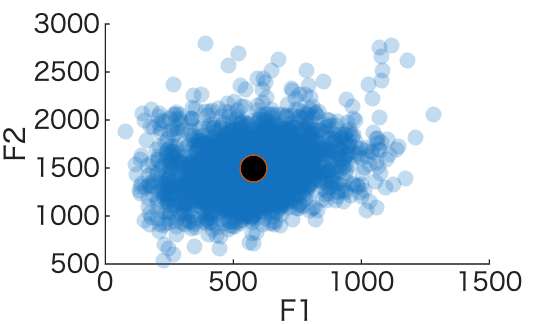

scatter(tblA, 'F1', 'F2', 'filled', ...
    'MarkerFaceAlpha', 0.25); hold on
plot(mean(tblA.F1), mean(tblA.F2), 'o', ...
    'MarkerFaceColor', 'k', 'MarkerSize', 10); hold off

for v  = unique(tblFormant.Vowel)'
    idx = strcmp(tblFormant.Vowel, v(1));
    tblFormant(idx,["zF1","zF2"]) = array2table(abs(zscore(table2array(tblFormant(idx,["F1","F2"])))));
end

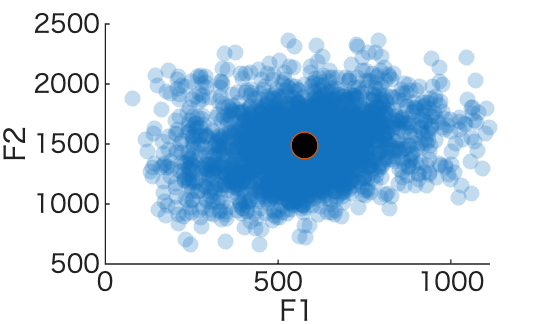


tblA = tblFormant(strcmp(tblFormant.Vowel, "a") & ...
    tblFormant.zF1 < 3 & tblFormant.zF2 < 3, :);

scatter(tblA, 'F1', 'F2', 'filled', ...
    'MarkerFaceAlpha', 0.25); hold on
plot(mean(tblA.F1), mean(tblA.F2), 'o', ...
    'MarkerFaceColor', 'k', 'MarkerSize', 10); hold off

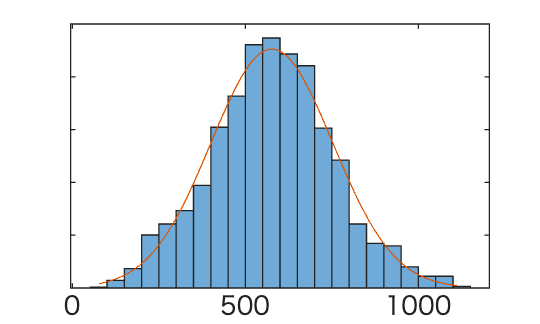

histogram(tblA.F1, 'Normalization', 'pdf'); hold on
yticklabels([]);
x = min(tblA.F1):max(tblA.F1);
plot(x, normpdf(x, mean(tblA.F1), std(tblA.F1))); hold off

 章末問題 5)

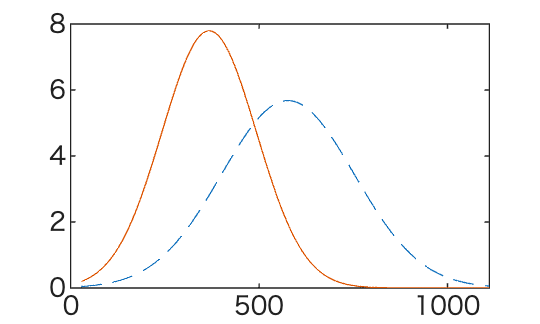

conditionRange = tblFormant.zF1 < 3 & tblFormant.zF2 < 3;
tblI = tblFormant(strcmp(tblFormant.Vowel, "i") & ...
    conditionRange, :);
xF1 = min(table2array(tblFormant(conditionRange, "F1"))):max(table2array(tblFormant(conditionRange, "F1")));
plot(xF1, height(tblA)*normpdf(xF1, mean(tblA.F1), std(tblA.F1)), '--'); hold on
plot(xF1, height(tblI)*normpdf(xF1, mean(tblI.F1), std(tblI.F1))); hold off

unknownF1 = 300;
likeA = normpdf(unknownF1, mean(tblA.F1), std(tblA.F1))

likeA = 6.6121e-04

likeI = normpdf(unknownF1, mean(tblI.F1), std(tblI.F1))

likeI = 0.0028

xF2 = min(table2array(tblFormant(conditionRange, "F2"))):max(table2array(tblFormant(conditionRange, "F2")));
scatter(tblA, "F1", "F2", "filled", "MarkerFaceAlpha", 0.15); hold on
xrange = xlim;
yrange = ylim;
muA = mean(table2array(tblA(:,["F1","F2"])))

muA = 1.0e+03 *

    0.5766    1.4892


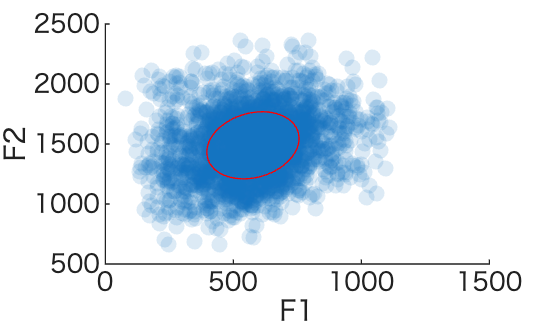

sigmaA = cov(tblA.F1,tblA.F2);
fcontour(@(x,y) mvnpdf([x y], muA, sigmaA), '-r', [xrange yrange], ...
    'LevelList', [mvnpdf([muA(1)+sqrt(sigmaA(1,1)), muA(2)], muA, sigmaA)]); hold off

tblAidx = randperm(height(tblA), round(height(tblA)/30));
tblASample = tblA(tblAidx,:);
tblIidx = randperm(height(tblI), round(height(tblI)/30));
tblISample = tblI(tblIidx,:);
scatter(tblASample, "F1", "F2", "filled", ...
    "MarkerFaceColor", 'b', ...
    "MarkerFaceAlpha", 0.25); hold on
scatter(tblISample, "F1", "F2", 'Marker', 'x', ...
    'MarkerEdgeColor', 'r', 'AlphaData', 0.3);
fcontour(@(x,y) mvnpdf([x y], muA, sigmaA), '-b', [xrange yrange], ...
    'LevelList', [mvnpdf([muA(1)+sqrt(sigmaA(1,1)), muA(2)], muA, sigmaA)]);

muI = mean(table2array(tblI(:,["F1","F2"])))

muI = 1.0e+03 *

    0.3676    1.9477


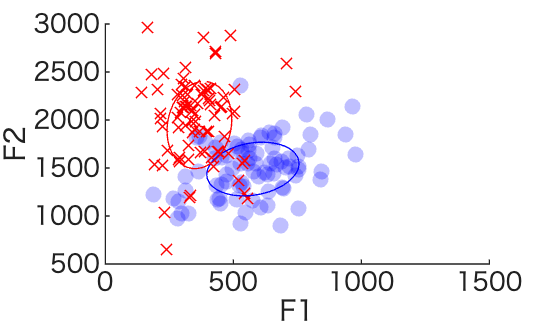

sigmaI = cov(tblI.F1,tblI.F2);
fcontour(@(x,y) mvnpdf([x y], muI, sigmaI), '-r', [xrange yrange], ...
    'LevelList', [mvnpdf([muI(1)+sqrt(sigmaI(1,1)), muI(2)], muI, sigmaI)]); hold off

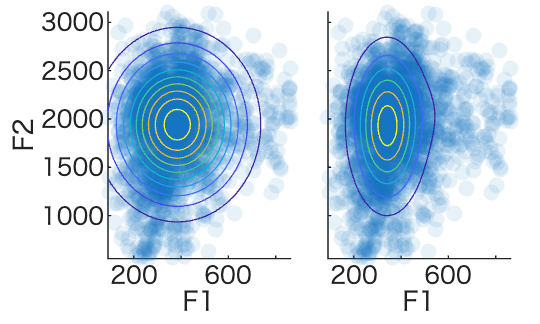

tblIall = tblFormant(strcmp(tblFormant.Vowel, "i"), :);
gmm1 = fitgmdist([tblIall.F1, tblIall.F2], 1, 'CovarianceType','diagonal');
gmm2 = fitgmdist([tblIall.F1, tblIall.F2], 2, 'CovarianceType','diagonal');
xRange = [min(tblI.F1) max(tblI.F1)];
yRange = [min(tblI.F2) max(tblI.F2)];

t = tiledlayout(1, 2);
t.TileSpacing = 'compact';
t.Padding = 'compact';
nexttile
scatter(tblIall, "F1", "F2", "filled", "MarkerFaceAlpha", 0.1); hold on
xlim(xRange); ylim(yRange)
fcontour(@(x,y) reshape(pdf(gmm1, [x(:) y(:)]), size(x)), [xRange yRange]); hold off
nexttile
scatter(tblIall, "F1", "F2", "filled", "MarkerFaceAlpha", 0.1); hold on
xlim(xRange); ylim(yRange)
fcontour(@(x,y) reshape(pdf(gmm2, [x(:) y(:)]), size(x)), [xRange yRange]); hold off
ylabel([]); yticklabels([])